Roche de Guzman - ENGG 101 / CSC 102 / MATH 147: Numerical Methods, Hofstra University

# ODEs Second Order: ode23s

    van der Pol equation with variables (t = independent and y = dependent) and constant ($\mu$)

        
$$\frac{d^2 y}{{dt}^2 }-\mu \left(1-y^2 \right)\frac{dy}{dt}+y=0$$


    Let $z=\frac{\textrm{dy}}{\textrm{dt}}$, hence $\frac{\textrm{dz}}{\textrm{dt}}=\frac{d^2 y}{{\textrm{dt}}^2 }$

    System of first order ODEs: 2 equations, 2 dependent (y and z)

        
$$\frac{dy}{dt}=z$$


        
$$\frac{dz}{dt}\;=\mu \left(1-y^2 \right)z-y$$


    Let vector of dependent variable $Y=\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$, hence *y = Y(1)* and *z = Y(2)*

clear; clc; close('all'); % clearing fxs

## Given

mu = 1000; % constant
f = @(t,Y) [Y(2); mu*(1-Y(1)^2)*Y(2)-Y(1)]; % ODE fxs: [dy/dt; dz/dt] with 2 inputs only
ti = 0; yi = 1; zi = 1; % initial values
tf = 6000; % final t

## Calculations and Results

tr = [ti tf]; % t range = [initial t, final t]
Yi = [yi; zi]; % initial Y = [initial y; initial z = dy/dt]
[t,Y] = ode23s(f,tr,Yi); % solve for the Y matrix
t = t' % transpose t vector

t = 	1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009


y = Y(:,1)' % extract and transpose the numerical y vector

y =     1.0000    1.0025    1.0109    1.0178    1.0215    1.0243    1.0261    1.0272    1.0281    1.0286    1.0291    1.0294    1.0296    1.0297    1.0298    1.0299    1.0300    1.0300    1.0300    1.0300    1.0300    1.0300    1.0300    1.0300    1.0299    1.0299    1.0298    1.0298    1.0297    1.0296    1.0294    1.0293    1.0290    1.0288    1.0284    1.0277    1.0265    1.0252    1.0239    1.0227    1.0215    1.0203    1.0191    1.0179    1.0167    1.0156    1.0144    1.0132    1.0120    1.0108


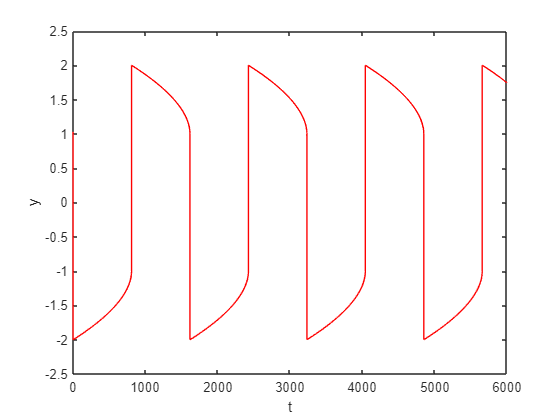

plot(t,y,'r-'); % plot of y vs. t
xlabel('t'); ylabel('y'); % annotations